xmax=4;
n=100;

N = ceil(n*xmax);
xmax = N/n; % make xmax an exact multiple of 1/n
x = (-N:N)'/n;
l = length(x);
c_exp=2;
C=0.2;
sen=1;
k=sen*n;
r=0.9;


c = zeros(1,l);
i = (x>0 & x<xmax);
c(i) = ((x(i)+1/2/n).^(c_exp+1)-(x(i)-1/2/n).^(c_exp+1))*(n/(c_exp+1));
i = (x==0);
c(i) = (1/2/n).^c_exp/(1+c_exp);
i = (x<0 & x>-xmax);
c(i) = ((abs(x(i))+1/2/n).^(c_exp+1)-(abs(x(i))-1/2/n).^(c_exp+1))*(n/(c_exp+1));
cN = n*r^(-N-1/2)*(-n*log(r))^(-c_exp-1)*gamma(c_exp+1)*gammainc(-log(r)*(N-1/2),c_exp+1,'upper');
c(1) = cN;
c(l) = cN;

A = [c;1/(1-r) ones(1,l-2) 1/(1-r)];
b = [C;1];

prob = optimproblem('ObjectiveSense','min');
p = optimvar('p',2*n*xmax+1,1,'LowerBound',0);
prob.Objective = sum(p(k+1:end).*log(p(k+1:end)./p(1:end-k)));
cons1 = A*p-b==0;
prob.Constraints.cons1 = cons1;

show(prob)


  OptimizationProblem : 

	Solve for:
       p

	minimize :
       sum((arg3(:) .* log((arg1(:) ./
       arg2(:)))))

       where:

         arg1 = p(101:801);
         arg2 = p(1:701);
         arg3 = p(101:801);


	subject to cons1:
       176.4987*p(1) + 15.92011*p(2)
     + 15.84041*p(3) + 15.76091*p(4)
     + 15.68161*p(5) + 15.60251*p(6)
     + 15.52361*p(7) + 15.44491*p(8)
     + 15.36641*p(9) + 15.28811*p(10)
     + 15.21001*p(11) + 15.13211*p(12)
     + 15.05441*p(13) + 14.97691*p(14)
     + 14.89961*p(15) + 14.82251*p(16)
     + 14.74561*p(17) + 14.66891*p(18)
     + 14.59241*p(19) + 14.51611*p(20)
     + 14.44001*p(21) + 14.36411*p(22)
     + 14.28841*p(23) + 14.21291*p(24)
     + 14.13761*p(25) + 14.06251*p(26)
     + 13.98761*p(27) + 13.91291*p(28)
     + 13.83841*p(29) + 13.76411*p(30)
     + 13.69001*p(31) + 13.61611*p(32)
     + 13.54241*p

lll=ones(l,1)/l;
p0.p = lll;
[sol,fval,exitflag,output] = solve(prob,p0)

Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.



sol = struct with fields:
    p: [801×1 double]


fval = 1.6850

exitflag =     SolverLimitExceeded


output = struct with fields:
              iterations: 1000
               funcCount: 2404
         constrviolation: 3.3307e-16
                stepsize: 2.9888e-04
               algorithm: 'interior-point'
           firstorderopt: 15.2706
            cgiterations: 1318
                 message: '↵Solver stopped prematurely.↵↵fmincon stopped because it exceeded the iteration limit,↵options.MaxIterations = 1.000000e+03.↵↵'
            bestfeasible: [1×1 struct]
     objectivederivative: "reverse-AD"
    constraintderivative: "closed-form"
                  solver: 'fmincon'


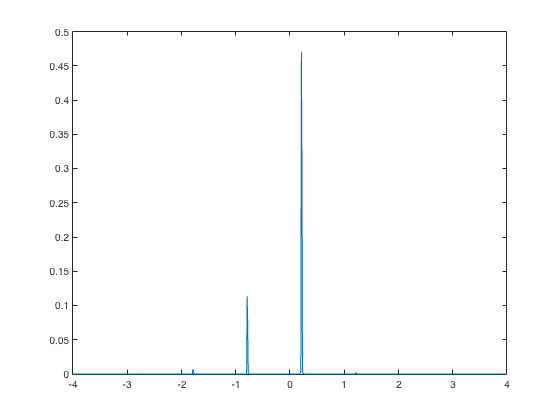

plot(x,sol.p)